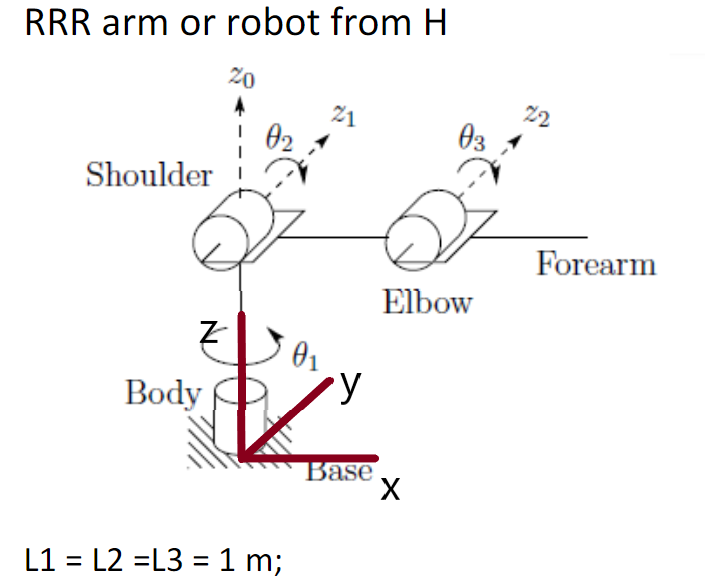

## Forward Kinematics


syms q1 q2 q3 real
L1 = 1;
L2 = 1;
L3 = 1;
H = Rz(q1) * Tz(L1) * Ry(q2) * Tx(L2) * Ry(q3) * Tx(L3);
H = simplify(H)

$$H = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{2}+q_{3}\right) & 0 & \cos\left(q_{2}+q_{3}\right) & 1-\sin\left(q_{2}\right)-\sin\left(q_{2}+q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right) \end{array}$$

## Jacobian By numerical method

R = H(1:3,1:3);
R_inv = [R' zeros(3,1);0 0 0 1];
% First joint
J1r = Rzd(q1) * Tz(L1) * Ry(q2) * Tx(L2) * Ry(q3) * Tx(L3) * R_inv;
J1r = simplify(J1r);
J1 =  [ J1r(1,4) J1r(2,4) J1r(3,4) J1r(3,2) J1r(1,3) J1r(2,1)].';

% Second joint
J2r = Rz(q1) * Tz(L1) * Ryd(q2) * Tx(L2) * Ry(q3) * Tx(L3) * R_inv;
J2r = simplify(J2r);
J2 =  [ J2r(1,4) J2r(2,4) J2r(3,4) J2r(3,2) J2r(1,3) J2r(2,1)].';

% Third joint
J3r = Rz(q1) * Tz(L1) * Ry(q2) * Tx(L2) * Ryd(q3) * Tx(L3) * R_inv;
J3r = simplify(J3r);
J3 =  [ J3r(1,4) J3r(2,4) J3r(3,4) J3r(3,2) J3r(1,3) J3r(2,1)].';

% Full jacobian matrix
J = [J1 J2 J3]

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{2} & -\sin\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}+q_{3}\right)-\cos\left(q_{2}\right) & -\cos\left(q_{2}+q_{3}\right)\\ 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right) \end{array}$$

## Jacobian position elements

J = J(1:3,1:3)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{2} & -\sin\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}+q_{3}\right)-\cos\left(q_{2}\right) & -\cos\left(q_{2}+q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right) \end{array}$$

## Joint trajectory q(t) from q(0) = (0,0,0) to q(2) = (2,3,4) with null initial and final velocities and accelerations. (polynomial)

clear
% Quintic polynomial
t_0 = 0;
t_f = 2;
% Initial joint angles
q_0 = [0 0 0]

q_0 =      0     0     0


% final joint angles
q_f =[2 3 4]

q_f =      2     3     4


% initial velocity and acceleration
q_0_dot = [0 0 0];
a_0 = [0 0 0];
% final velocity and acceleration
q_f_dot = [0 0 0];
a_f = [0 0 0];

n = 200 

n = 200

q_pos = zeros(n,3);
 q_vel = zeros(n,3);
 q_acc = zeros(n,3);
A = [1 t_0 t_0^2 t_0^3 t_0^4 t_0^5;
     0 1 2*t_0 3*t_0^2 4*t_0^3 5*t_0^4;
     0 0 2 6*t_0 12*t_0^2 20*t_0^3;
     1 t_f t_f^2 t_f^3 t_f^4 t_f^5;
     0 1 2*t_f 3*t_f^2 4*t_f^3 5*t_f^4;
     0 0 2 6*t_f 12*t_f^2 20*t_f^3]

A =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     2     0     0     0
     1     2     4     8    16    32
     0     1     4    12    32    80
     0     0     2    12    48   160


 for count = 1:3
     b = [q_0(count) q_0_dot(count) a_0(count) q_f(count) q_f_dot(count) a_f(count)]';
     %  inv(A) * b
     x =A\b;
     t = linspace(t_0,t_f,n);
     q_pos(:,count) = x(1)+x(2).*t + x(3).*t.^2 + x(4).* t.^3+ x(5).*t.^4 + x(6).*t.^5;
     q_vel(:,count) = x(2) + 2*x(3).*t + 3*x(4).* t.^2+ 4*x(5).*t.^3 + 5*x(6).*t.^4;
     q_acc(:,count) = 2*x(3)+ x(4)*6.*t + x(5)*12.*t.^2 + x(6)* 20.*t.^3;
 end

## Plotting of the joint angles, velocities, acceleration

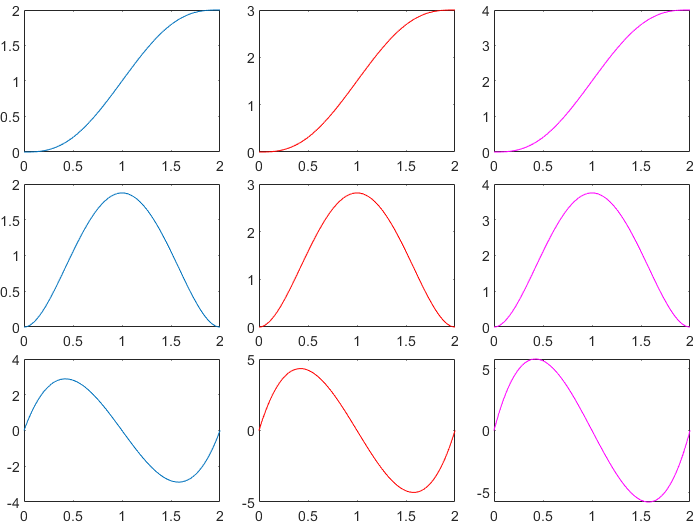

plt_2 = tiledlayout(3,3); % Requires R2019b or later
nexttile
plot(t,q_pos(:,1),'DisplayName','q1_pos')
nexttile
plot(t,q_pos(:,2),'r','DisplayName','q2_pos')
nexttile
plot(t,q_pos(:,3),'m','DisplayName','q3_pos')
nexttile
plot(t,q_vel(:,1),'DisplayName','q1_vel')
nexttile
plot(t,q_vel(:,2),'r','DisplayName','q2_vel')
nexttile
plot(t,q_vel(:,3),'m','DisplayName','q3_vel')
nexttile
plot(t,q_acc(:,1),'DisplayName','q1_acc')
nexttile
plot(t,q_acc(:,2),'r','DisplayName','q2_acc')
nexttile
plot(t,q_acc(:,3),'m','DisplayName','q3_acc')
plt_2.Padding = 'none';
plt_2.TileSpacing = 'none'; 

## Joint  trajectory  for  thefollowing  commands:  PTP (trapezoidal)

## q1 =  (0,0,0)  to q2=  (2,3,4)

## Controller command interpretation frequency 

## f = 100 Hz

## Maximum joint velocity –1 rad/s

## Maximum joint acceleration –10rad/s2

clear
% Initial joint angles
q_0 = [0 0 0]

q_0 =      0     0     0


% final joint angles
q_f = [2 3 4]

q_f =      2     3     4


% Max joint velocities
v = [1 1 1];
% Max joint acc
a = [10 10 10];

% Ta is constant across the 3 joints
Ta = v(1)/a(1)

Ta = 0.1000

% delta q of the 3 joints
delta_q = [q_f(:)-q_0(:)]

delta_q =      2
     3
     4


% Tf is different across the 3 joints
Tf = [(abs(delta_q(:))/v(1))+Ta]

Tf =     2.1000
    3.1000
    4.1000



%deltaT = 100 hz
deltaT = 1/100;

% Since Tf of the 3 joints are divisible by the deltaT of the controller
% there is no need to compute a new time

% We need to synchronize all 3 joints to arrive at the same time, we will 
% choose the longest time tf = 4.1
Tf_new = 4.1;
v_new = (delta_q(:))/(Tf_new - Ta)

v_new =     0.5000
    0.7500
    1.0000


a_new = v_new/Ta

a_new =     5.0000
    7.5000
   10.0000


b = zeros(3,8);
for NoJoints = 1:3
    % t0 --> ta:
    a10 = q_0(NoJoints);
    a11 = 0;
    a12 = 0.5*a_new(NoJoints);
    
    
    % ta --> tf-ta:
    a20 = q_0(NoJoints) + 0.5*a_new(NoJoints).*Ta.^2 - v_new(NoJoints).*Ta;
    a21 = v_new(NoJoints);
    
    % tf-ta --> tf:
    a30 = q_f(NoJoints) - 0.5*a_new(NoJoints).*Tf_new.^2;
    a31 = a_new(NoJoints).*Tf_new;
    a32 = -0.5*a_new(NoJoints);
    b(NoJoints,:) = [a10; a11; a12; a20; a21; a30; a31; a32];
end
b

b =          0         0    2.5000   -0.0250    0.5000  -40.0250   20.5000   -2.5000
         0         0    3.7500   -0.0375    0.7500  -60.0375   30.7500   -3.7500
         0         0    5.0000   -0.0500    1.0000  -80.0500   41.0000   -5.0000


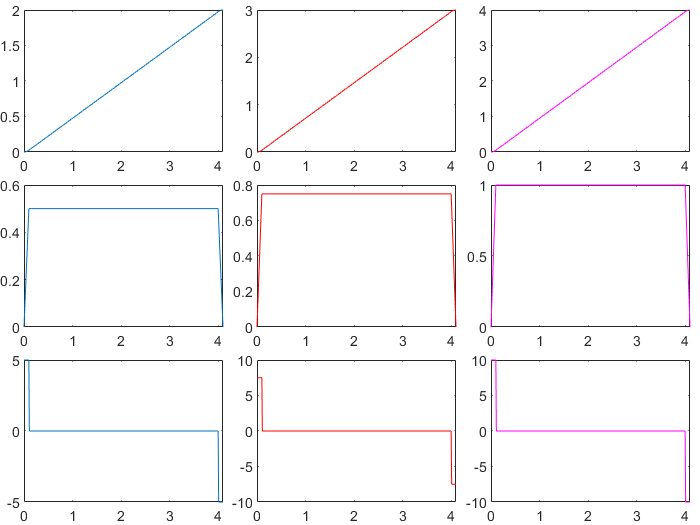

time = (0:deltaT:Tf_new);
q_pos = zeros(3,length(time));
q_vel = zeros(3,length(time));
q_acc = zeros(3,length(time));
for NoJoints = 1:3
    q_pos(NoJoints,:) = (b(NoJoints,1) +b(NoJoints,2).*time + b(NoJoints,3).*time.^2).*(time<=Ta)...
            +(b(NoJoints,4) +b(NoJoints,5).*time ).*(Ta < time).*(time <= (Tf_new-Ta))...
            +(b(NoJoints,6) +b(NoJoints,7).*time + b(NoJoints,8).*time.^2).*...
            ((Tf_new-Ta)<time).*(time <= Tf_new);
    q_vel(NoJoints,:) = (b(NoJoints,2)+ 2*b(NoJoints,3).*time).*(time<=Ta)...
        + b(NoJoints,5).*(Ta < time).*(time <= (Tf_new-Ta))...
        +(b(NoJoints,7)+ 2*b(NoJoints,8).*time).*((Tf_new-Ta)<time).*(time <= Tf_new);
    q_acc(NoJoints,:) = 2*b(NoJoints,3).*(time<=Ta)...
        + 0.*(Ta < time).*(time <= (Tf_new-Ta)) ...
        + 2*b(NoJoints,8).*((Tf_new-Ta)<time).*(time <= Tf_new);
end

plt_3 = tiledlayout(3,3); % Requires R2019b or later
nexttile
plot(time,q_pos(1,:),'DisplayName','q1_pos')
nexttile
plot(time,q_pos(2,:),'r','DisplayName','q2_pos')
nexttile
plot(time,q_pos(3,:),'m','DisplayName','q3_pos')
nexttile
plot(time,q_vel(1,:),'DisplayName','q1_vel')
nexttile
plot(time,q_vel(2,:),'r','DisplayName','q2_vel')
nexttile
plot(time,q_vel(3,:),'m','DisplayName','q3_vel')
nexttile
plot(time,q_acc(1,:),'DisplayName','q1_acc')
nexttile
plot(time,q_acc(2,:),'r','DisplayName','q2_acc')
nexttile
plot(time,q_acc(3,:),'m','DisplayName','q3_acc')
plt_3.Padding = 'none';
plt_3.TileSpacing = 'none'; 

## Joint trajectory for the following commands: LIN 

## –p1= (1, 0, 1) to p2=(√2/2, √2/2, 1.2)(trapezoidal)

## Controller command interpretation frequency 

## –f = 100 Hz

## Maximum linearvelocity –1 m/s

## Maximum linearacceleration –10m/s2

clear
p1 = [1 0 1];
p2 = [0.7071 0.7071 1.2];

tf = 10;
% No of points
N = 200;
% Divide our time axis by the number of points
t = linspace(0,tf,N);
% Get the waypoints across the straight line
px = ((p2(1)-p1(1))/tf).*t + p1(1);
py = ((p2(2)-p1(2))/tf).*t + p1(2);
pz = ((p2(3)-p1(3))/tf).*t + p1(3);

% Get the velocities at each waypoint
vx = ((p2(1)-p1(1))/tf);
vy = ((p2(2)-p1(2))/tf);
vz = ((p2(3)-p1(3))/tf);

vel = [vx vy vz]

vel =    -0.0293    0.0707    0.0200



Joint_config = zeros(3,100);
Joint_vel = zeros(3,100);
for count = 1:N
    point_vec = [px(count) py(count) pz(count)];
    Joint_config(:,count) = RRR_IK_waypoints(point_vec);
    if count == 1 || count == N
        Joint_vel(:,count) = 0;
    else
        J = CalculateJacobian(Joint_config(:,count));
        %inv(J)*vel
        Joint_vel(:,count) = J\vel';
    end
end

q_pos = zeros(3,25);
q_vel = zeros(3,25);
q_acc = zeros(3,25);
Q_pos = [];
Q_vel = [];
Q_acc = [];
for c = 1:N-1
    t_0 = t(c);
    t_f = t(c+1);
    A = [1 t_0 t_0^2 t_0^3;
         0 1 2*t_0 3*t_0^2;
         1 t_f t_f^2 t_f^3;
         0 1 2*t_f 3*t_f^2;]; % 200 point 3 joints
     % 1 - > 3 positions
     % 200 -> 600 positions
     for count = 1:3
         b = [Joint_config(count,c) Joint_vel(count,c) Joint_config(count,c+1) Joint_vel(count,c+1)]';
         % X = inv(A) * b
         x =A\b;
         ti = linspace(t_0,t_f,25);
         q_pos(count,:) = x(1)+x(2).*ti + x(3).*ti.^2 + x(4).* ti.^3;
         q_vel(count,:) = x(2) + 2*x(3).*ti + 3*x(4).* ti.^2;
         q_acc(count,:) = 2*x(3)+ x(4)*6.*ti;
     end
     Q_pos = [Q_pos q_pos];
     Q_vel = [Q_vel q_vel];
     Q_acc = [Q_acc q_acc];
end

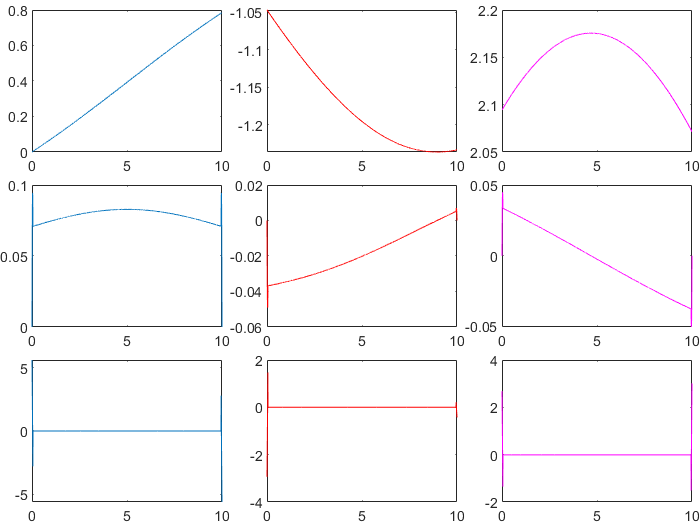

time = linspace(0,tf,4975);
plt_3 = tiledlayout(3,3); % Requires R2019b or later
nexttile
plot(time,Q_pos(1,:),'DisplayName','q1_pos')
nexttile
plot(time,Q_pos(2,:),'r','DisplayName','q2_pos')
nexttile
plot(time,Q_pos(3,:),'m','DisplayName','q3_pos')
nexttile
plot(time,Q_vel(1,:),'DisplayName','q1_vel')
nexttile
plot(time,Q_vel(2,:),'r','DisplayName','q2_vel')
nexttile
plot(time,Q_vel(3,:),'m','DisplayName','q3_vel')
nexttile
plot(time,Q_acc(1,:),'DisplayName','q1_acc')
nexttile
plot(time,Q_acc(2,:),'r','DisplayName','q2_acc')
nexttile
plot(time,Q_acc(3,:),'m','DisplayName','q3_acc')
plt_3.Padding = 'none';
plt_3.TileSpacing = 'none'; 

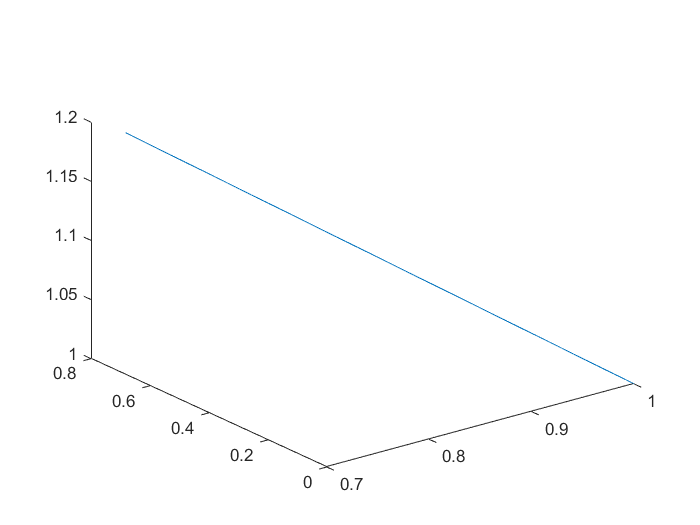

for p = 1:length(time)
fk= RRR_FK(Q_pos(:,p));
f(:,p) = fk(1:3,4)';
end
figure
plot3(f(1,:),f(2,:),f(3,:))